# System Control Analysis

% clc
% clear
% close all

### Polar Input

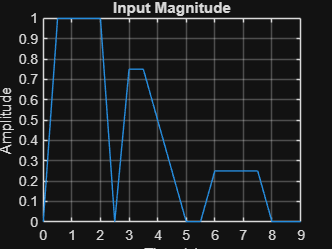

figure
plot(out.tout, out.input.signals(1).values);
grid on
xlabel("Time (s)")
ylabel("Amplitude")
title("Input Magnitude")
saveas(gcf, "figures/inp_mag.png")

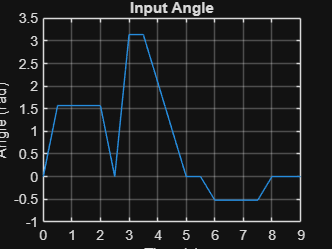


figure
plot(out.tout, out.input.signals(2).values);
grid on
xlabel("Time (s)")
ylabel("Angle (rad)")
title("Input Angle")
saveas(gcf, "figures/inp_ang.png")


% un_coord = unique([out.input.signals(1).values, out.input.signals(2).values], "rows");
% ts = out.tout(2) - out.tout(1);
% heat_values = zeros(size(out.tout));
% 
% for i = 1:length(un_coord)
%     mask = [out.input.signals(1).values, out.input.signals(2).values] == un_coord(i,:);
%     mask_1 = mask(:,1);
%     heat_values(mask_1) = sum(mask_1)*ts;
% end
% 
% figure
% title("Joystick Polar Coordinates")
% bubblelegend('Time','Location','eastoutside')
% polarbubblechart(out.input.signals(2).values, out.input.signals(1).values, heat_values, 'MarkerFaceAlpha', 0.20)

% saveas(gcf, "figures/polar_inp.png")

### Joystick Input

figure
plot(out.tout, out.joystick_inp.signals(1).values);
hold on
plot(out.tout, out.joystick_inp.signals(2).values);
hold off
grid on
xlabel("Time (s)")
ylabel("Coordinate")
title("Joystick Input")
legend(["Y", "X"])
saveas(gcf, "figures/joystick_inp.png")

### Joystick Output

figure
plot(out.tout, out.joystick_analogic_voltage.signals(1).values);
hold on
plot(out.tout, out.joystick_analogic_voltage.signals(2).values);
hold off
grid on
xlabel("Time (s)")
ylabel("Voltage (V)")
title("Joystick Output")
legend(["Y", "X"])
saveas(gcf, "figures/joystick_out.png")

### Joystick ADC Output

figure
plot(out.tout, out.adc.signals(1).values);
hold on
plot(out.tout, out.adc.signals(2).values);
hold off
grid on
xlabel("Time (s)")
ylabel("Bits")
title("Joystick Digital Output")
legend(["Y", "X"])
saveas(gcf, "figures/adc.png")

### Robot Speed Reference

figure
plot(out.tout, out.robot_speed_reference.signals(1).values);
grid on
xlabel("Time (s)")
ylabel("Linear Speed (m/s)")
title("Robot Reference Speed")
saveas(gcf, "figures/robot_speed_reference.png")


figure
plot(out.tout, out.robot_speed_reference.signals(2).values);
grid on
xlabel("Time (s)")
ylabel("Angular Velocity (rad/s)")
title("Robot Reference Angular Velocity")
saveas(gcf, "figures/robot_angular_velocity_reference.png")

### Wheel Speed Reference

figure
plot(out.tout, out.motor_speed_reference.signals(1).values);
hold on
plot(out.tout, out.motor_speed_reference.signals(2).values);
hold off
grid on
xlabel("Time (s)")
ylabel("Linear Speed (m/s)")
legend(["Left Motor", "Right Motor"])
title("Wheel Reference Speed")
saveas(gcf, "figures/wheel_speed_reference.png")

### PWM Conversion

figure
plot(out.tout, out.pwm_duty_cycle.signals(1).values);
hold on
plot(out.tout, out.pwm_duty_cycle.signals(2).values);
hold off
grid on
xlabel("Time (s)")
ylabel("Duty Cycle")
legend(["Left Motor", "Right Motor"])
title("PWM Converter")
saveas(gcf, "figures/pwm_duty_cycle.png")

### H-Bridge Driver Output

figure
plot(out.tout, out.h_bridge_voltage.signals(1).values);
hold on
plot(out.tout, out.h_bridge_voltage.signals(2).values);
hold off
grid on
xlabel("Time (s)")
ylabel("Voltage (V)")
legend(["Left Motor", "Right Motor"])
title("H-Bridge Driver Output")
saveas(gcf, "figures/h_bridge_out.png")

### Wheel Speed Output

figure
plot(out.tout, out.motor_speed_rbv.signals(1).values);
hold on
plot(out.tout, out.motor_speed_reference.signals(1).values);
hold off
grid on
xlabel("Time (s)")
ylabel("Speed (m/s)")
legend(["Output", "Reference"])
title("Left Wheel Output Speed")
saveas(gcf, "figures/left_wheel_speed_rbv.png")


figure
plot(out.tout, out.motor_speed_rbv.signals(2).values);
hold on
plot(out.tout, out.motor_speed_reference.signals(2).values);
hold off
grid on
xlabel("Time (s)")
ylabel("Speed (m/s)")
legend(["Output", "Reference"])
title("Right Wheel Output Speed")
saveas(gcf, "figures/right_wheel_speed_rbv.png")

### Robot Speed Output

figure
plot(out.tout, out.robot_speed_rbv.signals(1).values);
hold on
plot(out.tout, out.robot_speed_reference.signals(1).values);
hold off
grid on
xlabel("Time (s)")
ylabel("Linear Speed (m/s)")
legend(["Output", "Reference"])
title("Robot Reference Speed")
saveas(gcf, "figures/robot_speed_rbv.png")


figure
plot(out.tout, out.robot_speed_rbv.signals(2).values);
hold on
plot(out.tout, out.robot_speed_reference.signals(2).values);
hold off
grid on
xlabel("Time (s)")
ylabel("Angular Velocity (rad/s)")
legend(["Output", "Reference"])
title("Robot Output Angular Velocity")
saveas(gcf, "figures/robot_angular_velocity_rbv.png")

### Odometry

figure
plot(out.odometry.signals(1).values, out.odometry.signals(2).values, "-");
grid on
xlabel("X (m)")
ylabel("Y (m)")
title("Robot Position")
saveas(gcf, "figures/odometry_xy.png")


figure
plot(out.tout, out.odometry.signals(1).values);
grid on
xlabel("Time (s)")
ylabel("Position (m)")
title("Robot X Position")
saveas(gcf, "figures/odometry_x.png")


figure
plot(out.tout, out.odometry.signals(2).values);
grid on
xlabel("Time (s)")
ylabel("Position (m)")
title("Robot Y Position")
saveas(gcf, "figures/odometry_y.png")


figure
plot(out.tout, rad2deg(out.odometry.signals(3).values));
grid on
xlabel("Time (s)")
ylabel("Angle (deg)")
title("Robot X Position")
saveas(gcf, "figures/odometry_ang.png")